# Codes

clear ; close;

## I) 2D domain

### 1) Domain definition

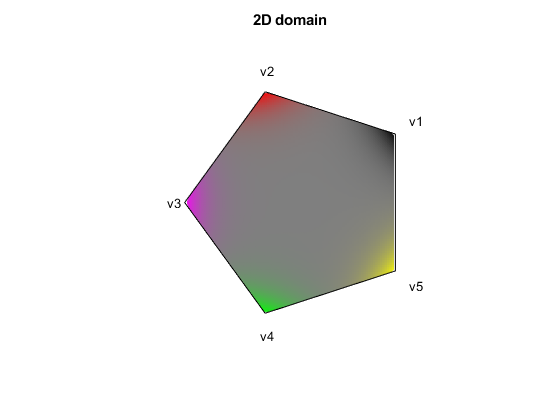

N = 5; % try different N
domain2d = Domain(N); 
figure()
domain2d.plot(); title("2D domain")

domain2d.plot_normalFan(); title("2D normal fan")
hold on

### 2) Projection

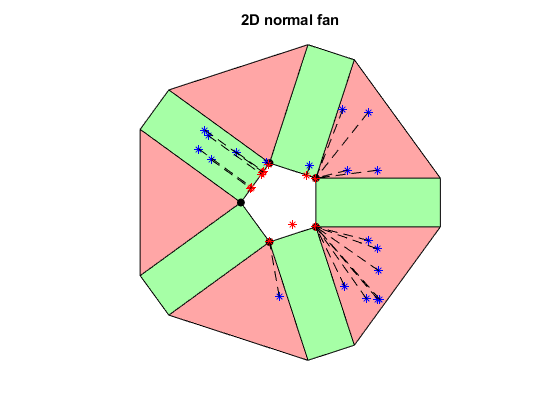

x2 = 5*(rand(20,2)-0.5);
x2_proj = domain2d.projection(x2);

scatter(x2(:,1),x2(:,2),"b*"); hold on
scatter(x2_proj(:,1),x2_proj(:,2),"r*");
plot([x2(:,1),x2_proj(:,1)].',[x2(:,2),x2_proj(:,2)].','--k')
axis equal
hold off

### 3) Computation of Wachspress basis functions

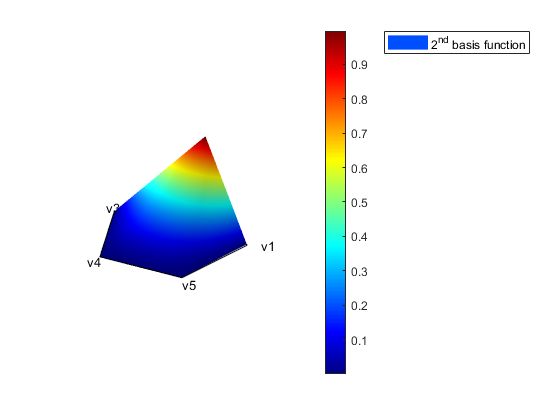

[w2,dw2dx] = wachspress(x2,domain2d);
domain2d.plot_Wachspress(2);

## II) 3D domain

### 1) Domain definition

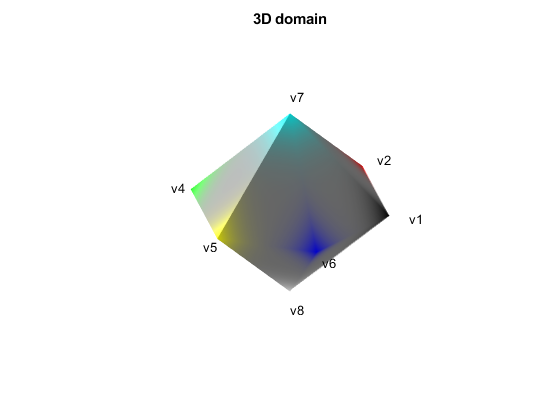

name = "diamond6"; % try with "tetra", "cube", "diamond3", "prism5"...
domain3d = Domain(name); 
figure()
domain3d.plot(); title("3D domain")

domain3d.plot_normalFan(); title("3D normal fan")
hold on

### 2 ) Projection

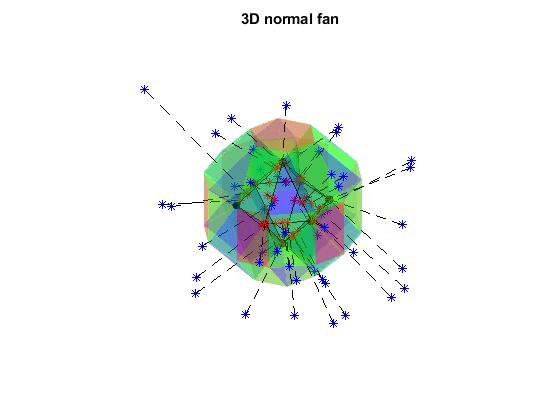

x3 = 5*(rand(50,3)-0.5);
x3_proj = domain3d.projection(x3);

scatter3(x3(:,1),x3(:,2),x3(:,3),"b*"); hold on
scatter3(x3_proj(:,1),x3_proj(:,2),x3_proj(:,3),"r*");
plot3([x3(:,1),x3_proj(:,1)].',[x3(:,2),x3_proj(:,2)].',[x3(:,3),x3_proj(:,3)].','--k')
axis equal
hold off

### 3) Computation of Wachspress basis functions

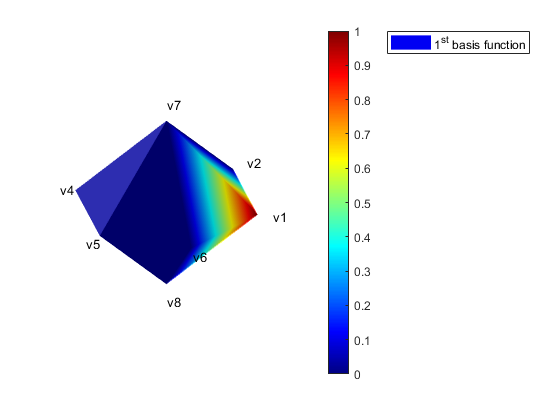

[w3,dw3dx] = wachspress(x3,domain3d);
domain3d.plot_Wachspress(1);